format long
trials = 5; % Number of trials

N_min = 0; % Range of N
N_max = 10000;
span = 100; % Span between N
arr_size = (N_max / span) + 1 % Determine arr size needed

arr_size =    101



N_range = N_min:span:N_max

N_range =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800        1900        2000        2100        2200        2300        2400        2500        2600        2700        2800        2900        3000        3100        3200        3300        3400        3500        3600        3700        3800        3900        4000        4100        4200        4300        4400        4500        4600        4700        4800        4900        5000        5100        5200        5300        5400        5500        5600        5700        5800        5900        6000        6100        6200        6300        6400        6500        6600        6700        6800        6900        7000        7100        7200        7300        7400        7500        7600        7700        7800        7900        8000        8100      

arr_size

arr_size =    101


N_range(1)

ans =      0



% For determining condition of A
A_condition = zeros(trials, 1);
A_mean_cond = zeros(arr_size, 1);

% QR Factorization

QR_times = zeros(trials,1); % Array of timing data for the QR factorization trials
QR_mean_time = zeros(arr_size, 1);

QR_errors = zeros(trials, 1);
QR_mean_error = zeros(arr_size, 1);

QR_condition = zeros(trials, 1);
QR_mean_cond = zeros(arr_size, 1);

% GE / LU factorization

GE_times = zeros(trials,1); % Array of timing data for the GE factorization trials
GE_mean_time = zeros(arr_size, 1);

GE_errors = zeros(trials, 1);
GE_mean_error = zeros(arr_size, 1);

GE_condition = zeros(trials, 1);
GE_mean_cond = zeros(arr_size, 1);

for j=2:arr_size % Skip N = 0
    
    j % Progress report
    
    N = N_range(j)
    
    for i=1:trials
        
        % Form a random matrix A and right-hand side b (normally distributed)
        A = randn(N,N);
        x = ones(N,1);
        
        b = A*x;
        
        A_condition(i) = cond(A);
        
        % Apply backslash and calculate time taken for QR factorization
        tic;
        [Q,R] = qr(A); % Compute the QR factorization of A        
        xhatQR = R\(Q.'*b);  % Solve the linear system (note that Q' is the transpose of Q)
        QR_times(i) = toc;
        
        QR_condition(i) = cond(Q) * cond(R);
        
        error = abs(xhatQR - x);
        QR_errors(i) = max(error);
        
        % Apply backslash and calculate time taken for GE factorization
        tic;
        xhatGE = A\b; % Solve the linear system using GE with partial pivoting
        GE_times(i) = toc;
        
        [L, U] = lu(A); % For calculating the condition of the LU matrix
        GE_condition(i) = cond(L) * cond(U);
        
        error = abs(xhatGE - x);
        GE_errors(i) = max(error);
        
    end
    
    A_mean_cond(j) = mean(A_condition);
    
    QR_mean_time(j) = mean(QR_times);
    QR_mean_error(j) = mean(QR_errors);
    QR_mean_cond(j) = mean(QR_condition);
    
    GE_mean_time(j) = mean(GE_times);
    GE_mean_error(j) = mean(GE_errors);
    GE_mean_cond(j) = mean(GE_condition);
    
end

j =      2


N =    100


j =      3


N =    200


j =      4


N =    300


j =      5


N =    400


j =      6


N =    500


j =      7


N =    600


j =      8


N =    700


j =      9


N =    800


j =     10


N =    900


j =     11


N =         1000


j =     12


N =         1100


j =     13


N =         1200


j =     14


N =         1300


j =     15


N =         1400


j =     16


N =         1500


j =     17


N =         1600


j =     18


N =         1700


j =     19


N =         1800


j =     20


N =         1900


j =     21


N =         2000


j =     22


N =         2100


j =     23


N =         2200


j =     24


N =         2300


j =     25


N =         2400


j =     26


N =         2500


j =     27


N =         2600


j =     28


N =         2700


j =     29


N =         2800


j =     30


N =         2900


j =     31


N =         3000


j =     32


N =         3100


j =     33


N =         3200


j =     34


N =         3300


j =     35


N =         3400


j =     36


N =         3500


j =     37


N =         3600


j =     38


N =         3700


j =     39


N =         3800


j =     40


N =         3900


j =     41


N =         4000


j =     42


N =         4100


j =     43


N =         4200


j =     44


N =         4300


j =     45


N =         4400


j =     46


N =         4500


j =     47


N =         4600


j =     48


N =         4700


j =     49


N =         4800


j =     50


N =         4900


j =     51


N =         5000


j =     52


N =         5100


j =     53


N =         5200


j =     54


N =         5300


j =     55


N =         5400


j =     56


N =         5500


j =     57


N =         5600


j =     58


N =         5700


j =     59


N =         5800


j =     60


N =         5900


j =     61


N =         6000


j =     62


N =         6100


j =     63


N =         6200


j =     64


N =         6300


j =     65


N =         6400


j =     66


N =         6500


j =     67


N =         6600


j =     68


N =         6700


j =     69


N =         6800


j =     70


N =         6900


j =     71


N =         7000


j =     72


N =         7100


j =     73


N =         7200


j =     74


N =         7300


j =     75


N =         7400


j =     76


N =         7500


j =     77


N =         7600


j =     78


N =         7700


j =     79


N =         7800


j =     80


N =         7900


j =     81


N =         8000


j =     82


N =         8100


j =     83


N =         8200


j =     84


N =         8300


j =     85


N =         8400


j =     86


N =         8500


j =     87


N =         8600


j =     88


N =         8700


j =     89


N =         8800


j =     90


N =         8900


j =     91


N =         9000


j =     92


N =         9100


j =     93


N =         9200


j =     94


N =         9300


j =     95


N =         9400


j =     96


N =         9500


j =     97


N =         9600


j =     98


N =         9700


j =     99


N =         9800


j =    100


N =         9900


j =    101


N =        10000


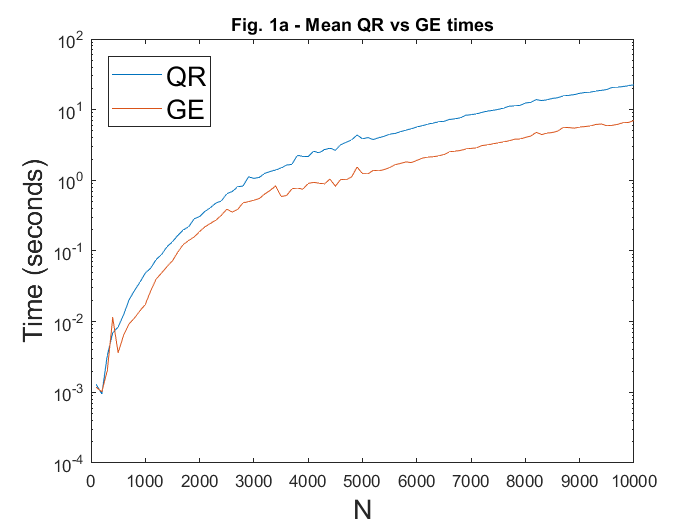


semilogy(N_range, QR_mean_time, N_range, GE_mean_time);
title('Fig. 1a - Mean QR vs GE times');
legend({'QR', 'GE'},'fontsize',16,'Location','northwest');
xlabel('N','fontsize',16);
ylabel('Time (seconds)','fontsize',16);

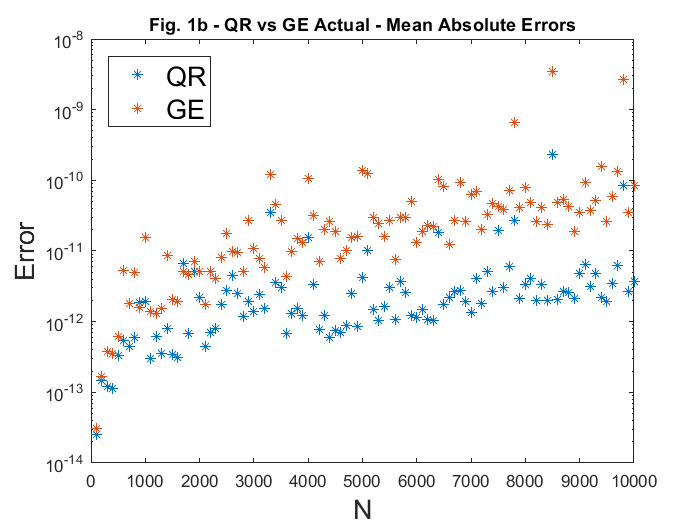


figure;semilogy(N_range, QR_mean_error, '*', N_range, GE_mean_error, '*');
title('Fig. 1b - QR vs GE Actual - Mean Absolute Errors');
legend({'QR', 'GE'},'fontsize',16,'Location','northwest');
xlabel('N','fontsize',16);
ylabel('Error','fontsize',16);

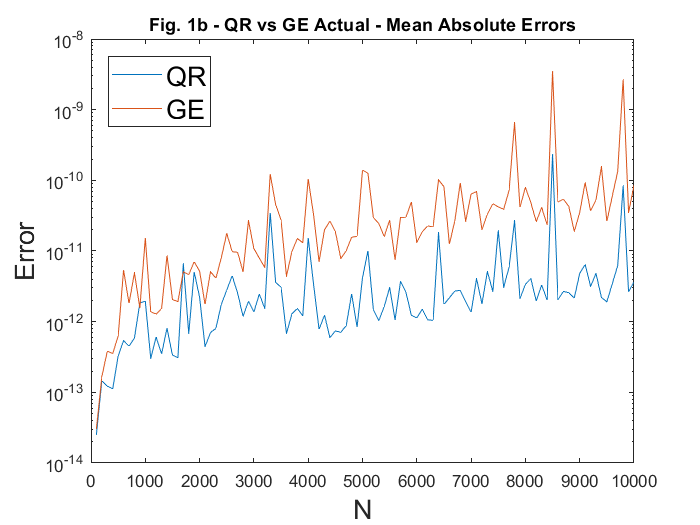


figure;semilogy(N_range, QR_mean_error, N_range, GE_mean_error);
title('Fig. 1b - QR vs GE Actual - Mean Absolute Errors');
legend({'QR', 'GE'},'fontsize',16,'Location','northwest');
xlabel('N','fontsize',16);
ylabel('Error','fontsize',16);

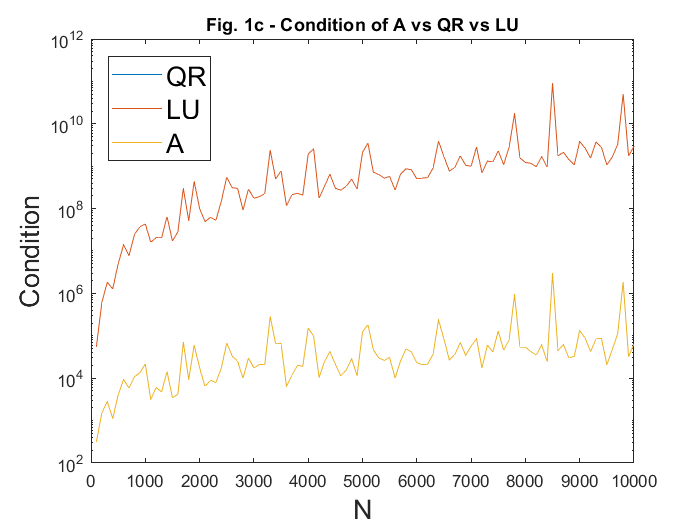

QR_mean_cond =    1.0e+06 *

                   0
   0.000324390025888
   0.001512509454310
   0.002844058928535
   0.001114101184671
   0.004034206197707
   0.009365625756825
   0.005815279384672
   0.010856628406563
   0.013394007706640
   0.021699294862600
   0.003154826540242
   0.006035566674132
   0.004752958248020
   0.014375235821331
   0.003482045204672
   0.004167319810440
   0.071309454804095
   0.009266409301654
   0.060964442078707
   0.017595169318355
   0.006386671088193
   0.008950403752913
   0.007953405490680
   0.017332493402752
   0.067897020883387
   0.033277361726911
   0.025231820296280
   0.010013695498816
   0.029948552968585
   0.017432775627255
   0.021172015904942
   0.020877096782928
   0.282556550596072
   0.064619667606123
   0.065909073228290
   0.006433569452837
   0.011660043947073
   0.020093351684261
   0.019110739565993
   0.152072424507319
   0.098846015819492
   0.010370401873772
   0.024501537051107
   0.042662501079784
   0.021366811307256
   0.

A_mean_cond =    1.0e+06 *

                   0
   0.000324390025888
   0.001512509454310
   0.002844058928535
   0.001114101184671
   0.004034206197707
   0.009365625756823
   0.005815279384672
   0.010856628406556
   0.013394007706641
   0.021699294862572
   0.003154826540242
   0.006035566674130
   0.004752958248020
   0.014375235821325
   0.003482045204672
   0.004167319810440
   0.071309454804171
   0.009266409301651
   0.060964442078858
   0.017595169318356
   0.006386671088193
   0.008950403752915
   0.007953405490679
   0.017332493402754
   0.067897020883147
   0.033277361727013
   0.025231820296252
   0.010013695498816
   0.029948552968617
   0.017432775627246
   0.021172015904941
   0.020877096782915
   0.282556550587070
   0.064619667606193
   0.065909073228713
   0.006433569452836
   0.011660043947076
   0.020093351684273
   0.019110739565993
   0.152072424507100
   0.098846015818777
   0.010370401873777
   0.024501537051086
   0.042662501079855
   0.021366811307242
   0.0



figure;semilogy(N_range, QR_mean_cond, N_range, GE_mean_cond, N_range, A_mean_cond);
title('Fig. 1c - Condition of A vs QR vs LU');
legend({'QR', 'LU', 'A'},'fontsize',16,'Location','northwest');
xlabel('N','fontsize',16);
ylabel('Condition','fontsize',16);